# Actividad 5.1 (Control de Posición)

A01737357 Daniel Castillo López

- **Implementar** el código requerido para generar el control de posición del robot tipo diferencial en los siguientes puntos deseados:

- **a) (1, 2) b) (3, 7) c) (6, 0)   d) (-4, 5)   e) (-6, 0)   f) (-1, 0)   g) (-7, -7)   h) (-2, -4)  ** **i****) (- 0.5, -0.5)   j) (1, -3)**

- **k) (3, -5) l) (8, 0) m) (0, -3)   n) (0, 9)   ñ) (0, -1)   o) (-5, -10)   p) (7, -7)   q) (3, -1)   r) (- 10, -10)   s) (10, 9)**

- **Genera** un análisis comparativo empleando **3** **valores** **de** **ganancias** **diferentes** y explica cual sería la mejor sintonización para posicionar al robot en cada punto (Incluye las gráficas de respuesta para cada caso).

clear
close all
clc

Representación de las coordenadas que debe de alcanzar

coordenadas = [1, 2; 3, 7; 6, 0; -4, 5; -6, 0; -1, 0; -7, -7; -2, -4; 
              -0.5, -0.5; 1, -3; 3, -5; 8, 0; 0, -3; 0, 9; 0, -1; 
              -5, -10; 7, -7; 3, -1; -10, -10; 10, 9];

tf = 15; 
ts = 0.1; 
t = 0:ts:tf; 
N = length(t);
sizeScreen = get(0,'ScreenSize');
scale = 4;

Tres valores distintos de la matriz de ganancia proporcional 

La ganancia intermedia (`K = 10`) ofrece un buen compromiso general entre rapidez y estabilidad. Pero para entornos más exigentes o trayectorias más corta

% Matrices de ganancia
Kd = cat(3, [5 0; 0 5], [10 0; 0 10], [15 0; 0 15]);
K_b = {'K = 5', 'K = 10', 'K = 15'};

for i = 1:size(coordenadas,1)
    hxd = coordenadas(i,1);
    hyd = coordenadas(i,2);

    %% ANIMACIÓN 3D con K=10
    K = Kd(:,:,2);  % Ganancia intermedia
    x1(1)=0; y1(1)=0; phi(1)=pi/2;
    hx(1)=x1(1); hy(1)=y1(1);
    v = zeros(1,N); w = zeros(1,N);

Calculamos el erroror de la posición del robot y nuestro objetivo, J se encarga de transformar el error de nuestro sistema de referncia y actualiza las posiciones del robot usando las velocidades

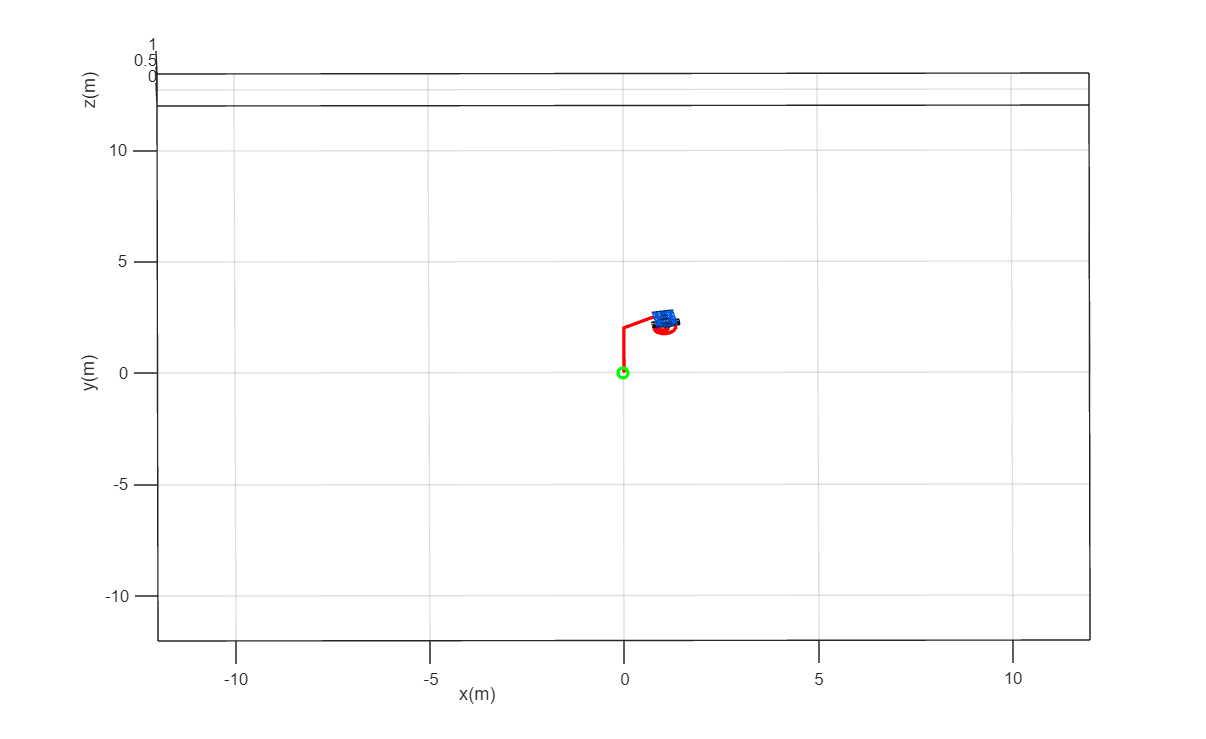

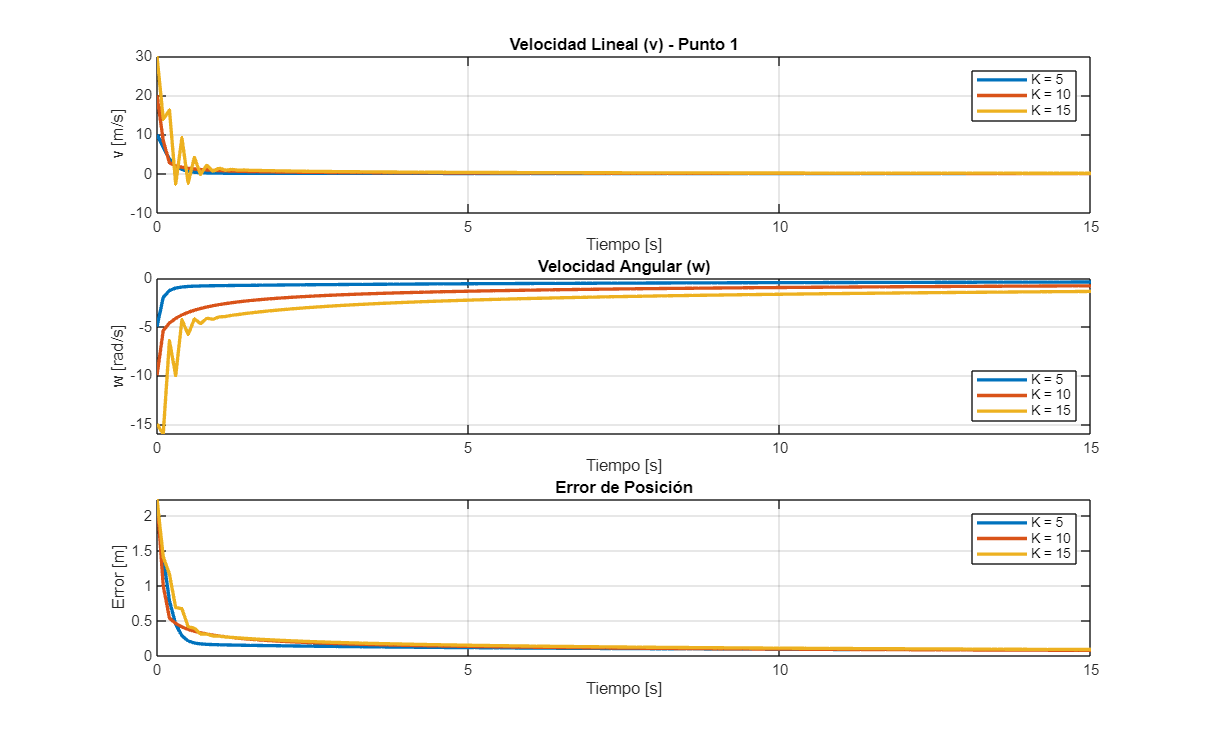

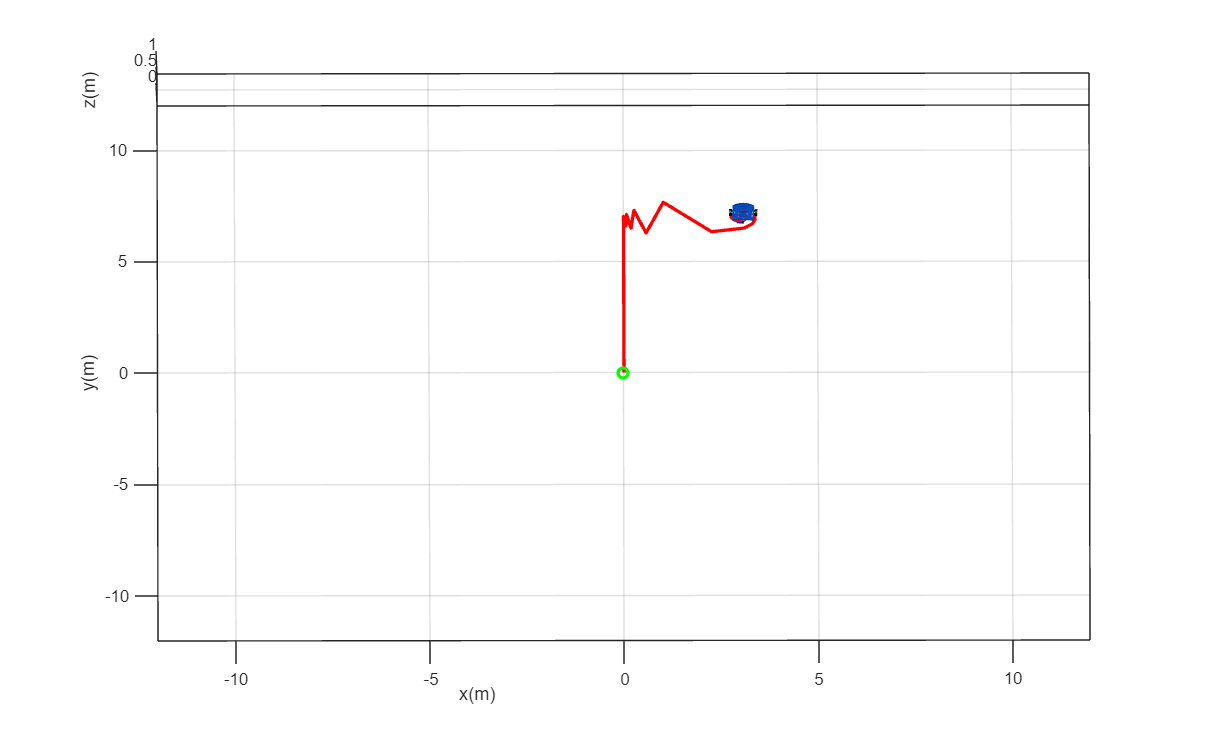

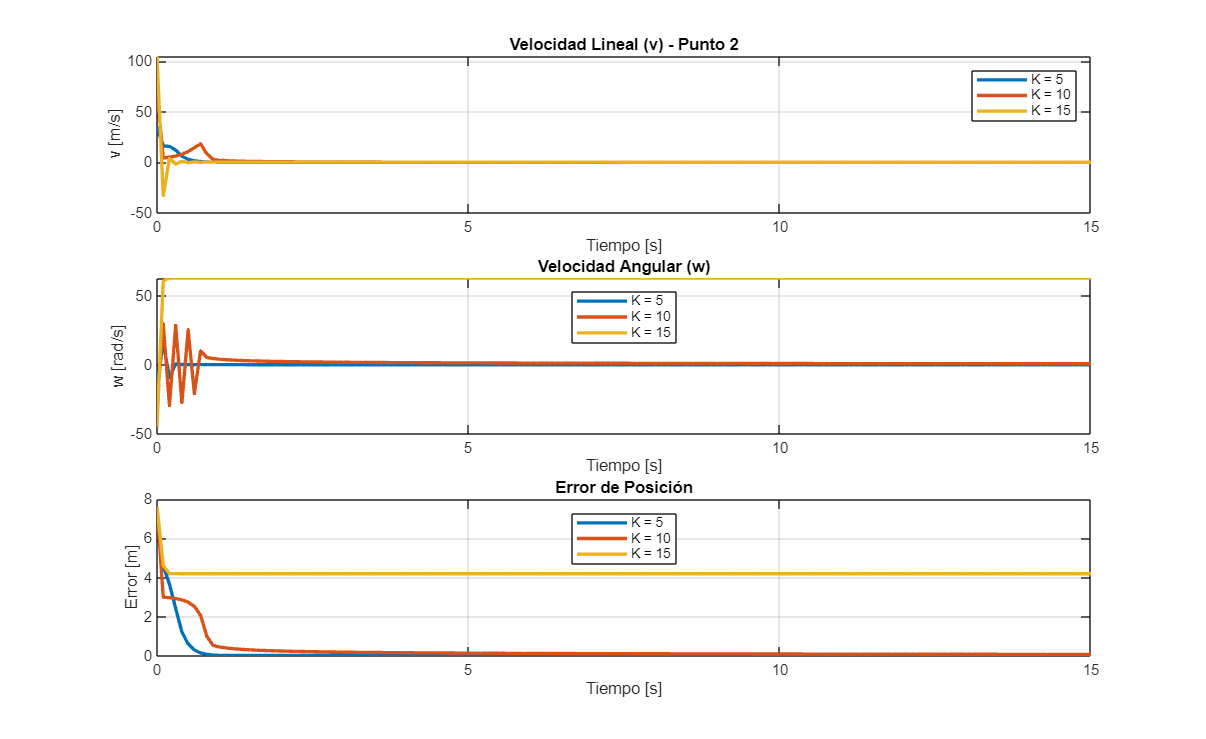

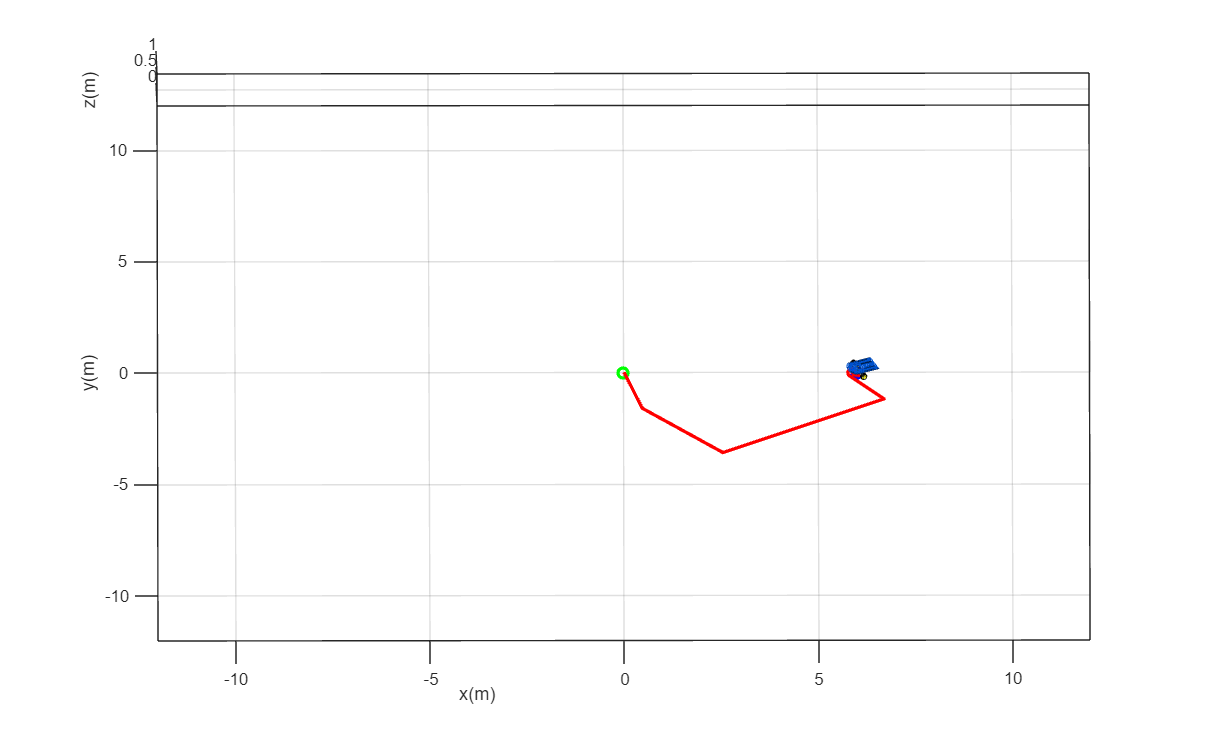

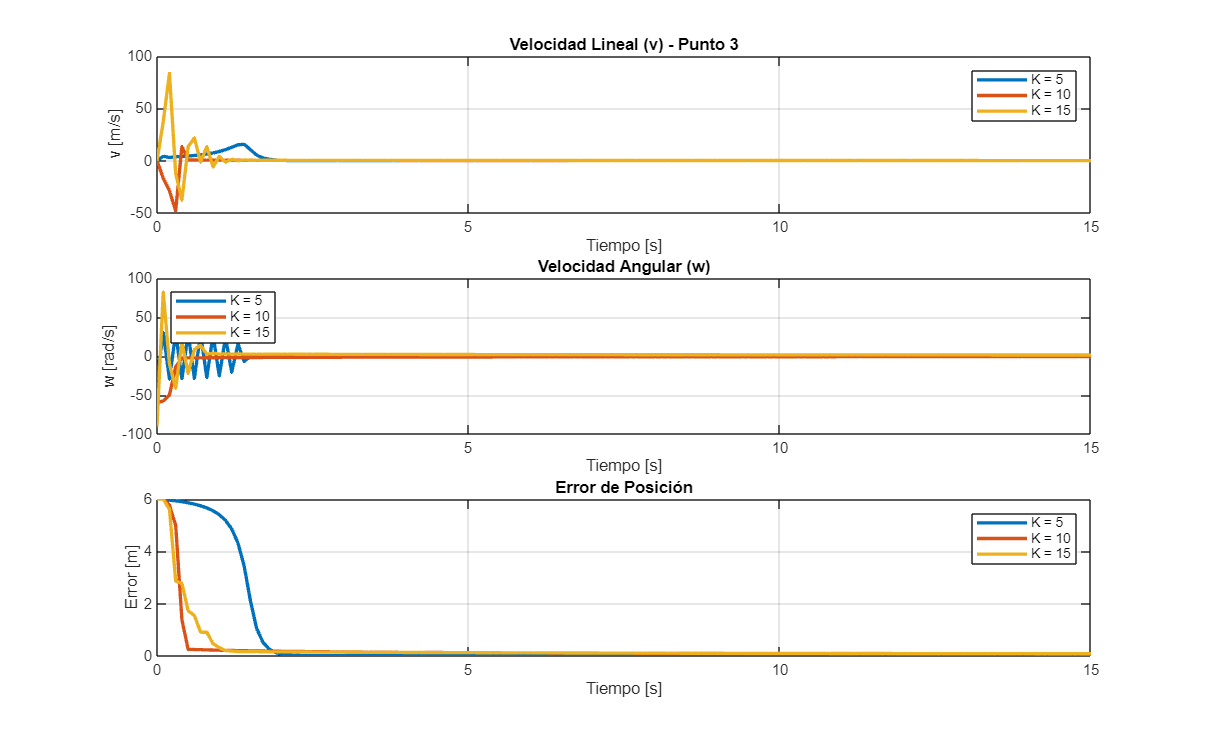

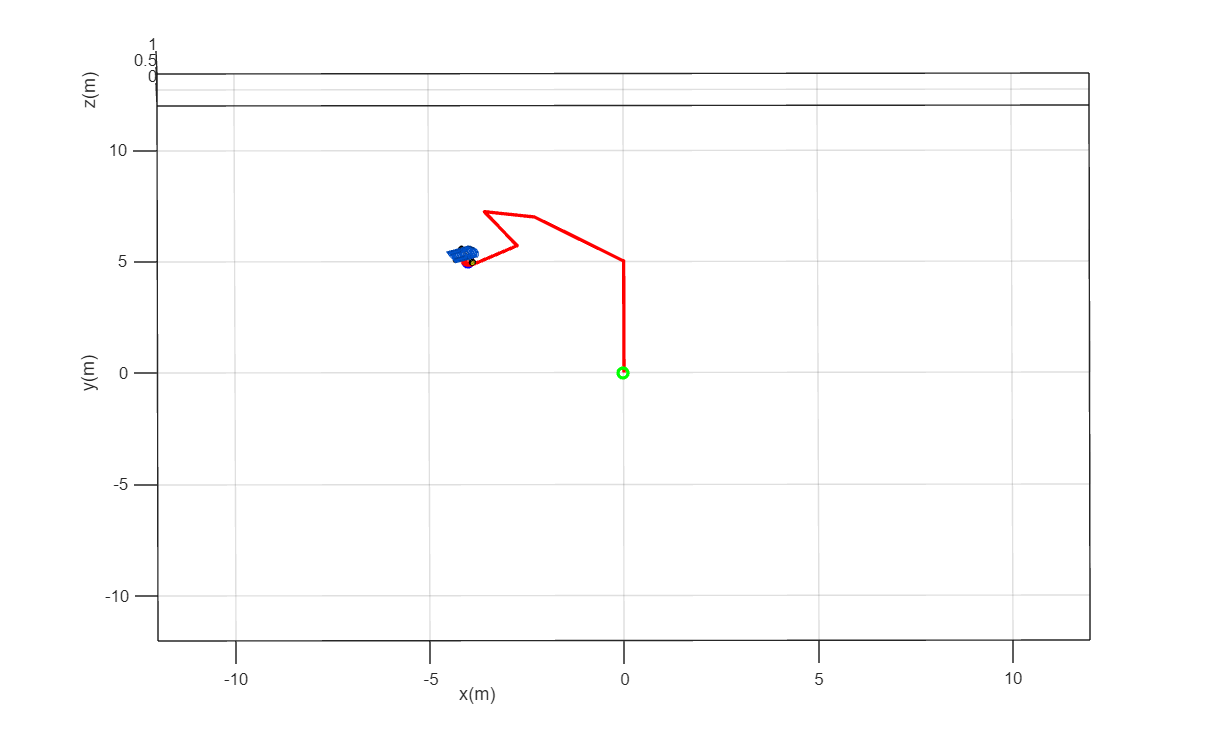

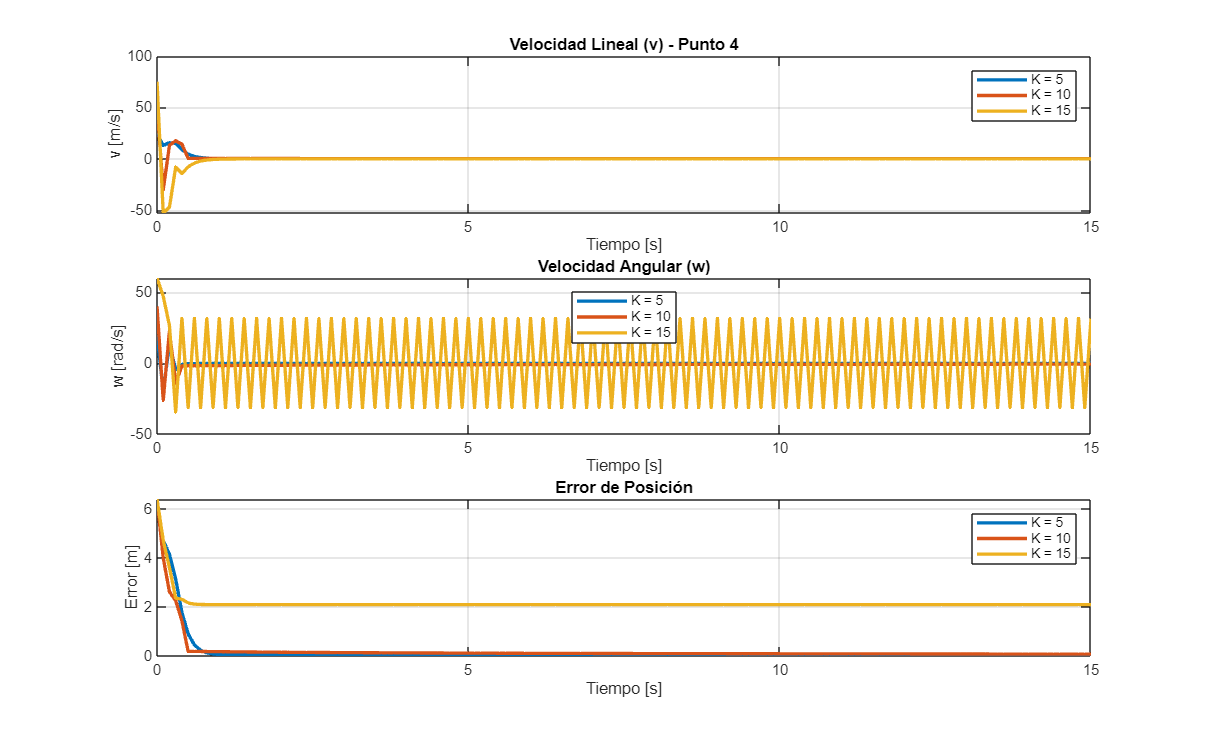

    for k = 1:N
        he = [hxd - hx(k); hyd - hy(k)];
        J = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);
        phi(k+1) = phi(k) + w(k)*ts;
        x1(k+1) = x1(k) + v(k)*cos(phi(k))*ts;
        y1(k+1) = y1(k) + v(k)*sin(phi(k))*ts;
        hx(k+1) = x1(k+1); hy(k+1) = y1(k+1);
    end

    scene = figure('Name',['Animación punto ' num2str(i) ' → (' num2str(hxd) ',' num2str(hyd) ')']);
    set(scene, 'Color','white', 'position', sizeScreen);
    camlight('headlight'); axis equal; grid on; box on;
    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
    view([-0.1 35]); axis([-12 12 -12 12 0 1]);
    MobileRobot_5;
    H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
    H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
    H3 = plot3(hxd, hyd, 0, 'bo', 'LineWidth', 2); 
    H4 = plot3(hx(1), hy(1), 0, 'go', 'LineWidth', 2);

    step = 1;
    for k = 1:step:N
        delete(H1); delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
        pause(ts);
    end

    fig = figure('Name',['Comparativa de Ganancias - Punto ' num2str(i)], 'Position', sizeScreen);

    for g = 1:3
        K = Kd(:,:,g); label = K_b{g};
        x1(1)=0; y1(1)=0; phi(1)=pi/2;
        hx(1)=x1(1); hy(1)=y1(1);
        v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

        for k = 1:N
            he = [hxd - hx(k); hyd - hy(k)];
            J = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];
            qpRef = pinv(J) * K * he;
            v(k) = qpRef(1);
            w(k) = qpRef(2);
            phi(k+1) = phi(k) + w(k)*ts;
            x1(k+1) = x1(k) + v(k)*cos(phi(k))*ts;
            y1(k+1) = y1(k) + v(k)*sin(phi(k))*ts;
            hx(k+1) = x1(k+1); hy(k+1) = y1(k+1);
            Error(k) = norm(he);
        end

        subplot(3,1,1)
        plot(t, v, 'LineWidth', 2); hold on; grid on;
        xlabel('Tiempo [s]'); ylabel('v [m/s]');
        title(['Velocidad Lineal (v) - Punto ' num2str(i)]);

        subplot(3,1,2)
        plot(t, w, 'LineWidth', 2); hold on; grid on;
        xlabel('Tiempo [s]'); ylabel('w [rad/s]');
        title('Velocidad Angular (w)');

        subplot(3,1,3)
        plot(t, Error, 'LineWidth', 2); hold on; grid on;
        xlabel('Tiempo [s]'); ylabel('Error [m]');
        title('Error de Posición');
    end

    subplot(3,1,1); legend(K_b, 'Location', 'Best');
    subplot(3,1,2); legend(K_b, 'Location', 'Best');
    subplot(3,1,3); legend(K_b, 'Location', 'Best');

    saveas(fig, ['Punto_' num2str(i) '_comparativa.png']);
    pause(1);
end
